## Pendulum with the visualisation

% _/_/_/_/_/_/_
%       |\
%  |    | \
%  | g  |  \ l 
%  V    | x \   (x=theta)
%       |    \
%       |     \
%       |      m
% 
% note: no energy dissipation
% note: no external force

clear
syms theta(t) m l g b L V T

% Kinetic energy
T = 0.5 * m * l^2 * diff(theta, 1, t)^2

$$T(t) = \frac{l^{2}\,m\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

% Potential energy
V = m * g * l * cos(theta)

$$V(t) = g\,l\,m\,\cos\left(\theta \left(t\right)\right)$$

% Energy dissipation
P = 0.5 * b * diff(theta, 1, t)^2

$$P(t) = \frac{b\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

% Lagrange equation
L = T - V

$$L(t) = \frac{l^{2}\,m\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}-g\,l\,m\,\cos\left(\theta \left(t\right)\right)$$

% Differentiations
diff_t_q_prim = diff(diff(L, 1, diff(theta)), 1, t)

$$diff\_t\_q\_prim(t) = l^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)$$

diff_q = diff(L, 1, theta)

$$diff\_q(t) = g\,l\,m\,\sin\left(\theta \left(t\right)\right)$$

diff_q_prim = diff(P, 1, diff(theta))

$$diff\_q\_prim(t) = b\,\frac{\partial }{\partial t}\theta \left(t\right)$$

% Final differential equation (u = d/dt(dL/dq') - dL/dq + dP/dq')
eqn = 0 == diff_t_q_prim - diff_q + diff_q_prim

$$eqn(t) = 0=m\,l^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+b\,\frac{\partial }{\partial t}\theta \left(t\right)-g\,m\,\sin\left(\theta \left(t\right)\right)\,l$$

eqn = isolate(eqn, diff(theta, 2))

$$eqn = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{b\,\frac{\partial }{\partial t}\theta \left(t\right)-g\,l\,m\,\sin\left(\theta \left(t\right)\right)}{l^{2}\,m}$$


% State space transition
syms x1(t) x2(t)
x = [x1 == theta; x2 == diff(theta)]

$$x(t) = \left(\begin{array}{c} x_{1}\left(t\right)=\theta \left(t\right)\\ x_{2}\left(t\right)=\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$


subs_eqn = subs(eqn, theta, x1);
subs_eqn = subs(subs_eqn, diff(x1), x2);
ss_eqs = [diff(x1) == x2; subs_eqn]

$$ss\_eqs(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{2}\left(t\right)\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=-\frac{b\,x_{2}\left(t\right)-g\,l\,m\,\sin\left(x_{1}\left(t\right)\right)}{l^{2}\,m} \end{array}\right)$$

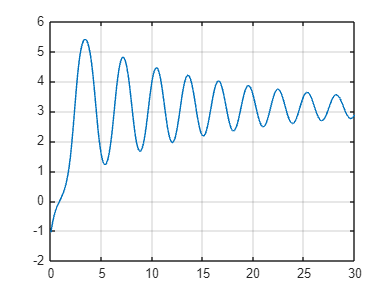

% subs_ss_eqs = subs(ss_eqs, [g, l, m, b], [9.81, 1, 1, 0.001])
% cond = [x1(0) == pi/8; x2(0) == 0];
% sol = dsolve(subs_ss_eqs) 

% Parametry
g = 9.81;
l = 2;
m = 1;
b = 0.5;

% Układ równań
odefun = @(t, x) [x(2); (m*g*l*sin(x(1)) - b*x(2))/(m*l^2)];

% Warunki początkowe
x0 = [-pi/3; 2.4];

% Przedział czasu
tspan = [0 30];

% Rozwiązanie numeryczne
[t, x] = ode45(odefun, tspan, x0);

% Wykres
plot(t, x(:,1)); grid on;

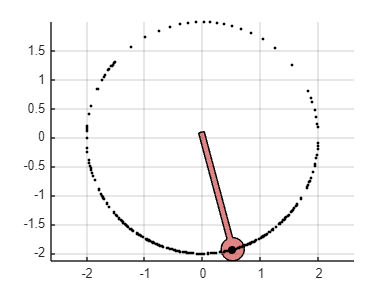


clear f_draw_patch
for i = 1:length(t)
    theta = x(i);
    x0 = l * sin(theta);
    y0 = l * cos(theta);
    
    fig = f_draw_patch(x0, y0, 0.2, 0.1, l-0.1, +pi/2 - theta);
    figure(fig);
    plot(x0, y0, '.k');
    pause(0.001);
end

% alpha = linspace(15*(-pi/180), 15*(pi/180), 1000);
% sina = sin(alpha);
% err = sina-alpha;
% plot(alpha, err); grid on;